# Fingerprint Analysis - Preprocessing and Feature Extraction

## Author: Roland Bruggmann

## School: Bern University of Applied Sciences BUAS and University of Bern

- Keywords: Biometrics, Computer Vision, Image Processing.

- Technology: MATLAB, Image Processing Toolbox.

## Description

Nowadays, digital authentication usually takes place via a user account, consisting of user name and password. When a user name is entered, an identity is propagated and the password is used for verification. However, stronger security is offered by biometric methods. A person provides a sample for identification and the sample is compared with the reference data in the system. 

An important physiological attribute of a natural person is his fingerprint which can serve as a measurable identifier. For this purpose, the impression must undergo an analysis so that characteristic features can be extracted and compared. With this live script we want to implement algorithms of known methods of biometrics for feature extraction at the fingerprint.

- Verification with physiological methods in biometry consists of five steps as follows:

- Capture: Capture the digital sample.

- Extraction: Preprocess and extraction of characteristics.

- Template creation: Creating a structured template according to the system.

- Query template database: Comparison of the template with the reference template in the system, vector as result.

- Compare matching: Evaluation of the vector, result positive or negative.

In civil applications such as smartphones and laptops, a digital sample is in most cases acquired using a sweep sensor. The pre-processing and extraction of the characteristics are carried out using digital image processing methods. Finally, the local coordinates of the characteristics serve as a template, both for the initial acquisition and for the samples. Finally, the template is compared with the reference data. The resulting vector is evaluated using statistical methods. 

For this challenge we focus on the second step: Preprocess and extraction of characteristics by the gradient based method of [Bazen/Gerez, 2002]. Further the Image Processing Toolbox from Mathworks is used for image processing. The raw image is a fingerprint from a database of [FVC, 2004].

% Clear matrices, close figures and clear cmd wnd.
clear variables; clear globals; close all; clc;

## 1. Capture

Our capture is reduced to a read in of a raw fingerprint image. We assume the image is in grayscales (white: 255, black: 0).

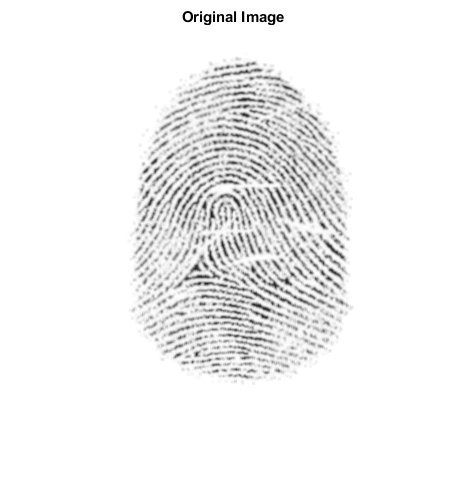


I = imread('C:/Users/Chaitanya/Documents/Internship/matlab_extraction/fingerprints/11_4.png');
[sizeX, sizeY] = size(I);
figure; imshow(I); axis off; title('Original Image');

## 2. Preprocessing

## 2.1 Quality Enhancement

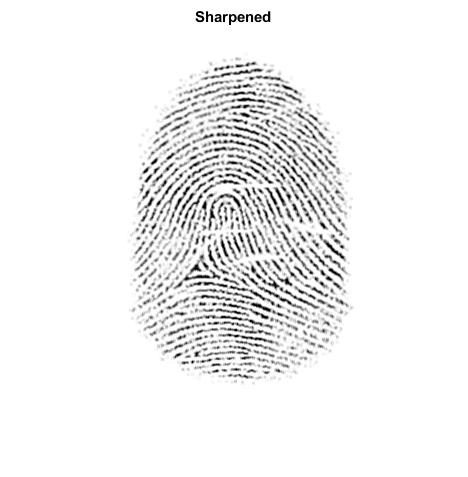

% Sharpen image
Is = imsharpen(I,'Radius', 1.5,'Amount',1.2); % 
figure; imshow(Is, []); axis off; title('Sharpened'); hold off;

To largen the image quality we apply a high-pass filter (Laplacian of Gaussian LoG). First, we transform the image to its frequency domain using a Fast Fourier Transformation (FFT) and a shift. Then we augment the amplitude of the dominant frequencies over relatively small regions and finally retransform the image back to the spatial domain by the use of an inverse FFT (IFFT).

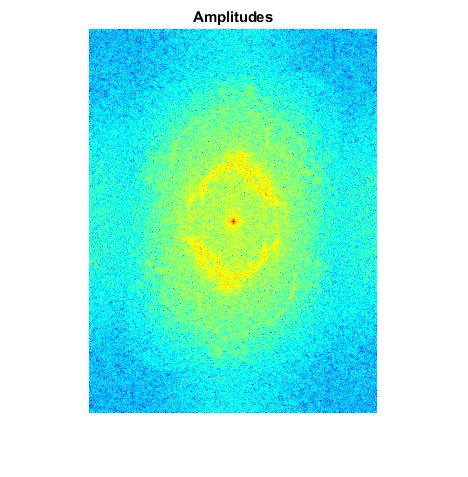

hsize = 7;
hsigma = 0.2;
h = fspecial('log', hsize, hsigma);

% Ih = imfilter(Is,h);
% Ih = I - Ih;

J = fftshift(fft2(double(Is)));
Jh = imfilter(J,h);
Jh = J - Jh;
Ih = abs(ifft2(ifftshift(Jh)));
% 
figure; imshow(log(max(abs(J),    1e-6)),[]), colormap(jet(64)); axis off; title('Amplitudes'); hold off;

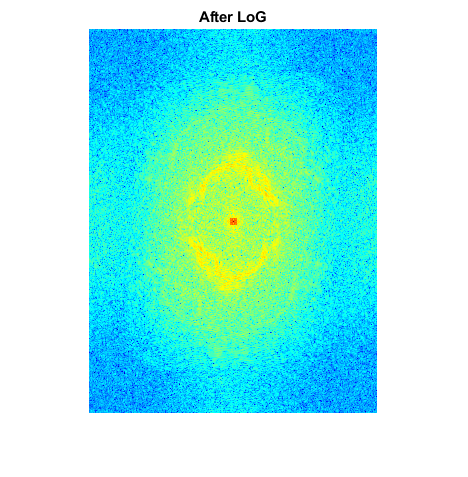

figure; imshow(log(max(abs(Jh), 1e-6)),[]), colormap(jet(64)); axis off; title('After LoG');  hold off;

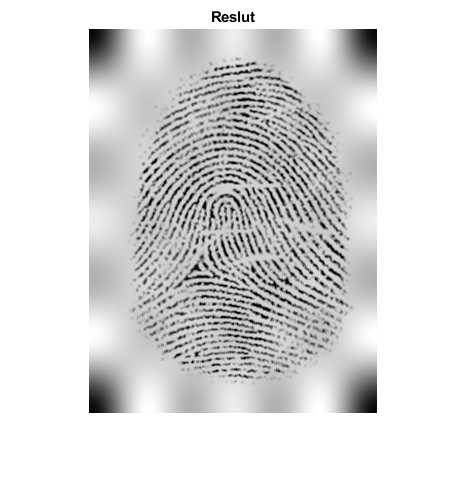

figure; imshow(Ih, []); axis off; title('Reslut'); hold off;

## 2.2 Variance, Quality and Segmentation

Segmentation using Gabor filters (cp. [Maltoni, 2009], chapter 3.4 Segmentation, p. 116-119).

function [ feature2DImage, Mask] = segmentTexture(I)
% Q = TODO
Iseg = double(Ih).*double(Mask);

figure; imshow(V, []); axis off; title('Variance'); hold off;
% figure; imshow(Q, []); axis off; title('Quality'); hold off;
figure; imshow(Iseg, []); axis off; title('Segmented'); hold off;

## 2.3 Gradients, Directions and Coherence

cp. [Maltoni, 2009], chapter 3.2 Local Ridge Orientation, especially 3.2.1 Gradient-based approaches, p. 102-106 and [Bazen/Gerez, 2002].


%Gradients Gx and Gy
hsize = 7;
hsigma = 1;
h = fspecial('gaussian', hsize, hsigma);

[hx,hy] = gradient(h);
Gx = filter2(hx, I);
Gy = filter2(hy, I);

% Local ridge orientation D (in radiant)
hsize = 17;
hsigma = 3;
h = fspecial('gaussian', hsize, hsigma);

Gxy = Gx.*Gy; Gxy = 2*filter2(h, Gxy);
Gxx = Gx.^2;  Gxx =   filter2(h, Gxx); 
Gyy = Gy.^2;  Gyy =   filter2(h, Gyy);
denom = sqrt((Gxx - Gyy).^2 + Gxy.^2) + eps;
sin2theta =       Gxy./denom;   sin2theta = filter2(h, sin2theta);
cos2theta = (Gxx-Gyy)./denom;   cos2theta = filter2(h, cos2theta);
D = pi/2 + atan2(sin2theta,cos2theta)/2;

% Coherence C as reliability of orientation
minima = (Gyy+Gxx)/2 - (Gxx-Gyy).*cos2theta/2 - Gxy.*sin2theta/2;
Imax = Gyy+Gxx - minima;
z = .001;
C = 1 - minima./(Imax+z);
C = C.*(denom>z);

%% Maskerading
GxMask = double(Gx).*double(mask);
GyMask = double(Gy).*double(Mask);
DMask  = double(D) .*double(Mask);
[x,y,u,v] = directionmap(DMask, 6, Iseg);
CMask = double(C).*double(Mask);

figure; imshow(Iseg,[]);  axis off; title('Gradients');  hold on; quiver(GxMask,GyMask); hold off;
figure; imshow(Iseg,[]);  axis off; title('Directions'); hold on; quiver(x,y,u,v,0,'.','linewidth',1); hold off;
figure; imshow(CMask,[]); axis off; title('Coherence');  hold off;

## 2.4 Binarisation and skeleton

Binarisation by threshold. Then we generate a skeleton by thinning the region. We remove pixels from the border and spur pixels 20 times.

thresh = graythresh(I);
binarised = imbinarize(I,thresh);
thinned  = ~bwmorph(~binarised,'thin',Inf); % 'skel'
skeleton =  bwmorph(thinned,'spur',20);

binarisedMask = binarised.*Mask;
skeletonMask = skeleton.*Mask;

figure; imshow(binarisedMask,[]); axis off; title('Binarised'); hold off;
figure; imshow(skeletonMask,[]); axis off; title('Skeleton'); hold off;

## 3. Feature Extraction

## 3.1 Global Features

To extraxt the global features we use the coherence map. This time, we choose a large sigma for the Gaussian weighting used to sum the gradient moments (cp. Maltoni, p. 124). Then we extract the minima and find the coordinates of global features.

[~, ~, ~, C2] = ridgeorient(I, 1, 17, 3);
C2Mask = double(C2).*double(Mask);
minima = ~imregionalmin(C2Mask);

candidateFeatures = double(~minima).*double(Mask);
[minimaY, minimaX] = find(candidateFeatures == 1);

figure; imshow(C2Mask, []); axis off; title('Coherence 2');
figure; imshow(minima, []); axis off; title('Minima'); hold on; plot(minimaX, minimaY, 'og', 'MarkerSize',10); hold off;
% Candidate region(s)
candidateRegion = ~imbinarize(C2Mask,0.5).*double(Mask);
figure; imshow(candidateRegion,[]); axis off; title('Candidate Region');
% Global features
candidateRegionWithMinima = and(candidateRegion,double(minima));
featureGlobal = xor(candidateRegion,candidateRegionWithMinima);
[globalY, globalX] = find(featureGlobal == 1);
figure; imshow(I,[]); axis off; title('Global Features'); hold on; plot(globalX, globalY, '*g','MarkerSize',20); hold off;

## 3.2 Minutiae

cp. [Maltoni, 2009], chapter 3.7 Minutiae Detection (p. 143-157).

Reference: Athi Narayanan S, [http://sites.google.com/site/athisnarayanan/s_athi1983@yahoo.co.in](http://sites.google.com/site/athisnarayanan/s_athi1983@yahoo.co.in) 

Im = ~xor(skeletonMask, maxk);

% Window
hsize = 3;
window = zeros(hsize);
border = floor(hsize/2);
center = border+1;

% Temporary data to work with
row = sizeX + 2*border;
col = sizeY + 2*border;
double temp(row,col);
temp = zeros(row,col);
temp( (center):(end-border), (center):(end-border) ) = Im(:,:);

% Minutiae containers
featureRidge       = zeros(row,col);
featureBifurcation = zeros(row,col);

for x = (center+10):(sizeX+border-10)
    for y = (center+10):(sizeY+border-10)
        % fill in window with values from temp
        e = 1;
        for k = x-border:x+border
            f = 1;
            for l = y-border:y+border
                window(e,f) = temp(k,l);
                f = f+1;
            end
            e=e+1;
        end
        if (window(center,center) == 0)
            featureRidge(x,y)       = sum(sum(~window));
            featureBifurcation(x,y) = sum(sum(~window));
        end
    end
end

% Resize area
featureRidge = featureRidge(1+border:end-border,1+border:end-border);
featureBifurcation = featureBifurcation(1+border:end-border,1+border:end-border);

## 3.2.1 Ridge endings

[ridgeY, ridgeX] = find(featureRidge == 2);
figure; imshow(skeletonMask); axis off; title('Ridge endings'); hold on; plot(ridgeX, ridgeY, 'ro'); hold off;
figure; imshow(I); axis off; title('Ridge endings'); hold on; plot(ridgeX, ridgeY, 'ro'); hold off;

## 3.2.2 Bifurcations

[bifurcationY, bifurcationX] = find(featureBifurcation == 4);
figure; imshow(skeletonMask); axis off; title('Bifurcations'); hold on; plot(bifurcationX, bifurcationY, 'bs'); hold off;
figure; imshow(I); axis off; title('Bifurcations'); hold on; plot(bifurcationX, bifurcationY, 'bs'); hold off;
end

## Discusson

As the extracted ridge endings on the skeleton show, these are generally well recognized, but too many of them are detected. This is mainly due to the fact that many grooves that could actually be bridged are interrupted by the imprecise binarisation by means of threshold values. Even a moving average threshold is no remedy (cp. [Maltoni, 2009], page 116). Only a local binarization could lead to a better result. The same applies to the bifurcations: It can be seen from the skeleton that binarization and the subsequent thinning out of the grooves has formed connections or even islands. In addition, forks are often detected three times over. The use of different structural elements would be appropriate here.

## References

[Bazen/Gerez, 2002]: Bazen, Asker M. and Gerez, Sabih H.: Systematic Methods for the Computation of the Directional Fields and Singular Points of Fingerprints. IEEE Transactions on Pattern Analysis and Machine Intelligence, vol. 24, No. 7, July 2002 (p. 905-919).

[FVC04]: International Competition for Fingerprint Verification Algorithms FCV 2004, Database 3 Set B, BioLab, University of Bologna, Online: [http://bias.csr.unibo.it/fvc2004](http://bias.csr.unibo.it/fvc2004) .

[Maltoni, 2009]: Maltoni, D. et al.: Handbook of Fingerprint Recognition, 2. ed., chapter 3: Fingerprint Analysis and Representation. Springer 2009.